clear all
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t)

m1=1; m2=1;L=2; IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;
rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];
g=9;

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1]

$$eq1 = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)=\mathrm{F1x}\left(t\right)+\mathrm{F2x}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y_{1}\left(t\right)=\mathrm{F1y}\left(t\right)+\mathrm{F2y}\left(t\right)-9 \end{array}\right)$$

MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0])

$$MF3G2 = \left(\begin{array}{c} 0\\ 0\\ -\cos\left(\theta_{2}\left(t\right)\right)\,\mathrm{F3x}\left(t\right)-\sin\left(\theta_{2}\left(t\right)\right)\,\mathrm{F3y}\left(t\right) \end{array}\right)$$

eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0]

$$eq5 = \left(\begin{array}{c} x_{1}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)=0\\ \cos\left(\theta_{1}\left(t\right)\right)+y_{1}\left(t\right)=0 \end{array}\right)$$

%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))]

$$eq6 = \left(\begin{array}{c} \sin\left(\theta_{1}\left(t\right)\right)+x_{1}\left(t\right)=x_{2}\left(t\right)-\sin\left(\theta_{2}\left(t\right)\right)\\ y_{1}\left(t\right)-\cos\left(\theta_{1}\left(t\right)\right)=\cos\left(\theta_{2}\left(t\right)\right)+y_{2}\left(t\right) \end{array}\right)$$

%F2 and F3 must be related. 
eq7=F2==-F3

$$eq7 = \left(\begin{array}{c} \mathrm{F2x}\left(t\right)=-\mathrm{F3x}\left(t\right)\\ \mathrm{F2y}\left(t\right)=-\mathrm{F3y}\left(t\right) \end{array}\right)$$

Initial Conditions:
Y0/YP0:
x1: 0.000000 x1t:0.000000
y1: -1.000000 y1t:0.000000
x2: 0.707107 x2t:0.100000
y2: -2.707107 y2t:0.100000
F1x: 0.589416 F1xt:0.000000
F1y: 13.312956 F1yt:0.000000
F2x: 1.178832 F2xt:0.000000
F2y: -4.312956 F2yt:0.000000
F3x: -1.178832 F3xt:0.000000
F3y: 4.312956 F3yt:0.000000
theta1: 0.000000 theta1t:0.000000
theta2: 0.785398 theta2t:0.141421
Dx1t: 0.000000 Dx1tt:1.768248
Dy1t: 0.000000 Dy1tt:-0.000000
Dx2t: 0.100000 Dx2tt:-1.178832
Dy2t: 0.100000 Dy2tt:-4.687044
Dtheta1t: 0.000000 Dtheta1tt:1.768248
Dtheta2t: 0.141421 Dtheta2tt:-6.648481


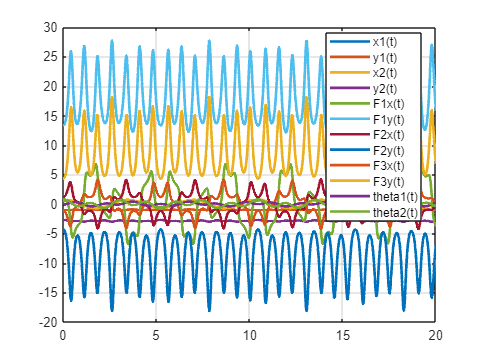


DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];
soln=mechanicsAsDAE(DES,PositionConstraints,[],...
    [rG1;rG2;F1;F2;F3;theta1;theta2],0,20,...
    {theta1==0,diff(x1,t)==0,theta2(t)==pi/4,"Dx2t==0.1"});

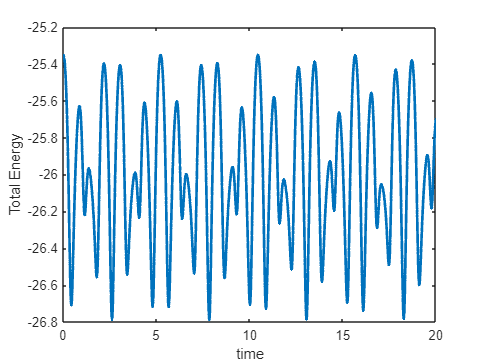

KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2);
PotentialEnergy=m1*soln.y1+m2*soln.y2*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

[pureDEs,PPs]=analyzeSystem(DES,PositionConstraints,[],...
    [rG1;rG2;F1;F2;F3;theta1;theta2],[theta1,diff(theta1),theta2,diff(theta2)])

There are 20 equations, and 12 unknown time-varying functions.
The non-algebraic (force) functions are:
x1(t)
y1(t)
x2(t)
y2(t)
theta1(t)
theta2(t)

Adding in all constraints, and counting pure symbols (so that x, Dxt, Dxtt count as 3 symbols) I get:
equations: 20
symbols:24
free parameters: 4.

Expected number of state variables: 4



$$pureDEs = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=\frac{81\,\sin\left(\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right)\right)+243\,\sin\left(\theta_{1}\left(t\right)\right)+24\,\sigma_{1}\,\sigma_{2}+18\,\sin\left(\sigma_{5}\right)\,\sigma_{3}}{\sigma_{4}}\\ \frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=-\frac{243\,\sin\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-189\,\sin\left(\theta_{2}\left(t\right)\right)+96\,\sigma_{1}\,\sigma_{3}+18\,\sin\left(\sigma_{5}\right)\,\sigma_{2}}{\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{4}=18\,\cos\left(\sigma_{5}\right)-46\\ \sigma_{5}=2\,\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right) \end{array}$$

soln=timeStepODESystem(pureDEs,[theta1,theta2],[theta1==0,theta2==0,diff(theta1)==1,diff(theta2)==1], ...
    [0,20],PPs)

soln = struct with fields:
           t: [416×1 double]
      theta1: [416×1 double]
      theta2: [416×1 double]
    Dtheta1t: [416×1 double]
    Dtheta2t: [416×1 double]
        Dx1t: [416×1 double]
       Dx1tt: [416×1 double]
        Dx2t: [416×1 double]
       Dx2tt: [416×1 double]
        Dy1t: [416×1 double]
       Dy1tt: [416×1 double]
        Dy2t: [416×1 double]
       Dy2tt: [416×1 double]
         F1x: [416×1 double]
         F1y: [416×1 double]
         F2x: [416×1 double]
         F2y: [416×1 double]
         F3x: [416×1 double]
         F3y: [416×1 double]
          x1: [416×1 double]
          x2: [416×1 double]
          y1: [416×1 double]
          y2: [416×1 double]


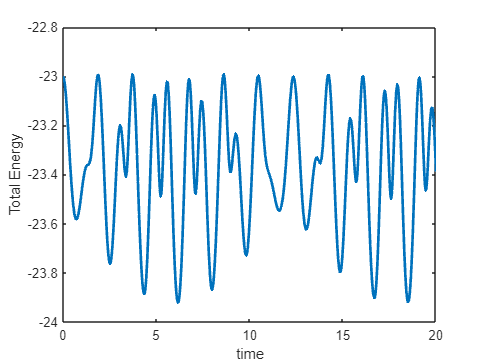

KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2);
PotentialEnergy=m1*soln.y1+m2*soln.y2*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')